clear all;
clf;
load impulse_responses.mat

Error using load
impulse_responses.mat is not found in the current folder or on the MATLAB path, but exists in:
    /home/frank/OneDrive/Documents/Git/Array_Processing_proj/proj2
    /home/frank/Downloads/Array projects/3Array_Processing-main/project_2
    /home/frank/Downloads/Array projects/2Array-Processing-main
    /home/frank/Downloads/EE4715-Array_Processing-main/Project2

Change the MATLAB current folder or add its folder to the MATLAB path.

warning('off', 'MATLAB:singularMatrix');
warning('off', 'MATLAB:nearlySingularMatrix');

fs=16000;
%implement noise period
start_noise_seconds=0;
noise_samples=start_noise_seconds*fs;
num_samples=500000;

[clean_speech,~] = audioread('clean_speech.wav');
clean_speech = clean_speech(1:num_samples);
clean_speech=[zeros(noise_samples,1);clean_speech];
clean_speech_energy=sum(clean_speech.^2);


[babble, ~] = audioread('babble_noise.wav');
babble = babble(1:num_samples);
babble=norm_sig(babble,clean_speech_energy);
babble=[babble;zeros(noise_samples,1)];


[clean_speech_2, ~] = audioread('clean_speech_2.wav');
clean_speech_2 = clean_speech_2(1:num_samples);
clean_speech_2=norm_sig(clean_speech_2,clean_speech_energy);
clean_speech_2=[clean_speech_2;zeros(noise_samples,1)];

[artificial_nonstat_noise, ~] = audioread('aritificial_nonstat_noise.wav');
artificial_nonstat_noise = artificial_nonstat_noise(1:num_samples);
artificial_nonstat_noise=norm_sig(artificial_nonstat_noise,clean_speech_energy);
artificial_nonstat_noise=[artificial_nonstat_noise;zeros(noise_samples,1)];
num_samples=num_samples+noise_samples;

M=4; % Number of microphones
sigma = 0.1; % Variance of the white noise
%read in impulse responses
H = load('impulse_responses.mat');
h_target=getImpulse(H,5);
h_1=getImpulse(H,1);
h_2=getImpulse(H,2);
h_3=getImpulse(H,2);



%construct multiple sound_sources
x_time = zeros(4, num_samples+399);
s_time = zeros(4, num_samples+399); 
in_time=zeros(4, num_samples+399);

%speech2,babble, artificial, white
% interference_ratio=[0.3,0.2,0.2,0.2,0.1];
interference_ratio=[1,0,0,0];

SNR_mic_before = zeros(1, 4);
max_SNR=5;
SNR_factor=0;
for i = 1:4
    target_signal=conv(clean_speech,h_target(i,:));
    interferer1=conv(clean_speech_2,h_1(i,:))*interference_ratio(1);
    interferer2=conv(babble,h_2(i,:))*interference_ratio(2);
    interferer3=conv(artificial_nonstat_noise,h_3(i,:))*interference_ratio(3);
    white_noise = randn(size(target_signal))*interference_ratio(4);

    noise_interferers=(interferer1+interferer2+interferer3+white_noise);
    if i==1
        SNR_factor=sqrt(sum(target_signal.^2)/(10^(max_SNR/10)*sum(noise_interferers.^2)));
    end

    % noise_interferers=noise_interferers*SNR_factor;
    signal=target_signal+noise_interferers;

    x_time(i,:) = signal;
    s_time(i,:) = target_signal;
    in_time(i,:)=interferer1+interferer2+white_noise;
    
    % Calculate the SNR
    SNR_mic_before(i) = 10 * log10(sum(abs(target_signal).^2) / sum(abs(signal - target_signal).^2));
    filename = sprintf('microphone%d.wav', i);
    audiowrite(filename, signal, fs);
end
 SNR_mic_before
 figure;
 plot(x_time(1,:))
 figure;
 plot(s_time(1,:))



% Short time fourier transform
window_time=0.02;
% L = 2^nextpow2(window_time*fs);
L=window_time*fs;
Overlap=0.50;
[x_f,K] = s_t_f_t(x_time,L,Overlap);

%add spatially white noise
for k =1:K
    x_f(:,k,:)=squeeze(x_f(:,k,:))+0.0025*(randn([M,L])+randi([M,L]))/sqrt(2);
end 
[n_f,~] = s_t_f_t(in_time,L,Overlap);



x=reshape(x_f,[size(x_f,1),size(x_f,3),size(x_f,2)]);

Unrecognized function or variable 'x_f'.

 
% Add spatial white noise for each frequency bin
sigma_n = .0025;
for k=1:size(x, 2)
    x(:, k, :) = squeeze(x(:, k, :)) + sigma_n.*(randn([size(x, 1) size(x, 3)]) + 1i* randn([size(x, 1) size(x, 3)]))./sqrt(2);
end

% Calculate the ATF from the impulse response
H_t = squeeze(s_t_f_t(h_target,L,Overlap)).';

% Delay-and-Sum Beamforming
S_est = zeros(1, K, L);
R_x=zeros([L,4,4]);
R_n=zeros([L,4,4]);
R_x_tilde=zeros([L,4,4]);

alpha=0.1;
tol = 1e-10; % Tolerance for numerical stability

fft_coef_sum = zeros([K 1]);
% Iterate over all frames
for k = 1:K
    % Voice Activity Detection, apply thresholding on 
    fft_coef_sum(k) = sum(sum(abs(x_f(:, k, :))).^2);
end
threshold = .3*mean(fft_coef_sum);


for k = 1:K
    for l = 1:L
        
      if fft_coef_sum(l) > threshold
            %update R_x
            R_x(l, :, :) = alpha.*squeeze(R_x(l, :, :)) + (1-alpha).*x_f(:, k, l)*x_f(:, k, l)';
      else
            R_n(l, :, :) = alpha.*squeeze(R_n(l, :, :)) + (1-alpha).*n_f(:, k, l)*n_f(:, k, l)';

      end
       
        %whiten the singal x
        R_n_root=sqrtm(squeeze(R_n(l,:,:)));
        x_f_tilde=inv(R_n_root)*x_f(:,k,l);
        x_f_tilde(isnan(x_f_tilde))=0;

        %calculate spatial covariance of whitened x
        R_x_tilde_temp=x_f_tilde*x_f_tilde';
        % R_x_tilde(l, :, :) = alpha.* squeeze(R_x_tilde(l, :, :)) + ...
        % (1-alpha).*R_x_tilde_temp;

        % get atf from eigen decomposition
        [U, V] = eig(squeeze(R_x_tilde(l,:,:)));
        sigma_s = (V(1,1)-V(2,2));
        a_tilde = U(:, 1);
        
        %estimate R_s
        R_s_tilde=sigma_s^2.*(a_tilde*a_tilde');
        R_s_hat=R_n_root* R_s_tilde*R_n_root;

        [U, V] = eig(R_s_hat);
        a=U(:,1);

        
   
        % %MVDR beamformer
        R_x_inv = inv(reshape(R_x(l, :,:),[4,4]));
        w = R_x_inv * a / (a' * R_x_inv * a);
        w(isinf(w))=1;
        S_est(1, k, l) = w' * squeeze(x_f(:, k, l));
    end
end

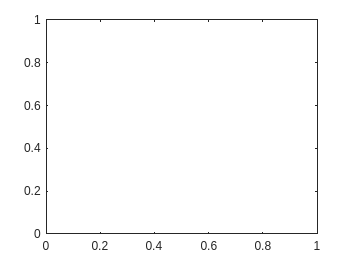

% Inverse STFT to get the time-domain signal
s_est = i_s_t_f_t(S_est, L, Overlap);

plot(s_est);

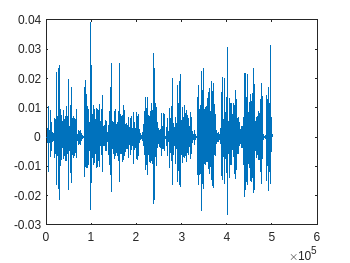

hold on;
plot(x_time(1,:));
hold off;


plot(x_time(1,:));
hold on;
plot(s_est);
hold off;


audiowrite('beamformed_output.wav', s_est, fs);

10 * log10(sum(s_time(1,1:500000).^2) / sum((s_est(1,1:500000) - s_time(1,1:500000)).^2))

ans = NaN


% Inverse STFT to get the time-domain signal
output_signal = i_s_t_f_t(S_est, L, Overlapp);
plot(real(output_signal))
10 * log10(sum(clean_mic(1,1:500000).^2) / sum((output_signal(1:500000) - clean_mic(1,1:500000)).^2))


function H = getImpulse(impulse_response,index)    
    % Access the element from the struct
    impulses = reshape(struct2array(impulse_response), 5, 4, 400);
    H = squeeze(impulses(index,:,:));
end

%short time fourier transform
function [S, K, win] = s_t_f_t(signal, L, Overlap)
    
    M = size(signal, 1);
    N = size(signal, 2);
    D = round(L * (1 - Overlap));  % Step size
    K = floor((N - L) / D) + 1;    % Number of segments
    S = zeros(M, K, L);
    win = hann(L, 'periodic')';    % Window function
    
    for m = 1:M
        for k = 1:K
            start = (k - 1) * D + 1;
            stop = start + L - 1;
            segment = signal(m, start:stop) .* win;
            S(m, k, :) = fft(segment);
        end
    end
end

function signal_out = norm_sig(in_signal,target_energy)
    factor= sqrt(target_energy/sum(in_signal.^2));
    signal_out = in_signal *factor;
end

function signal = i_s_t_f_t(S, L, Overlap)

    [M, K, ~] = size(S);
    D = round(L * (1 - Overlap));  % Step size
    N = L + (K - 1) * D;           % Total length of the reconstructed signal
    signal = zeros(M, N);
    win = hann(L, 'periodic')';
    win_sum = zeros(1, N);         % To normalize the windowing effect
    
    for m = 1:M
        for k = 1:K
            start = (k - 1) * D + 1;
            stop = start + L - 1;
            segment = real(ifft(squeeze(S(m, k, :))).');
            signal(m, start:stop) = signal(m, start:stop) + segment ;
        end
    end
    
end